# Tutorial: Lumping

Lumping is a model reduction technique for PBPK models that maintains their mechanistic interpretation. In this tutorial, you will see how the lumping approach is implemented in the Computational Physiology Toolbox.

#### Example: Defining a lumped model

To illustrate how a model is lumped, we allocate two individuals: one for a full PBPK model, the other for the lumped model:

indv = Individual('Virtual',2);

The full PBPK model is specified as explained in the Tutorial "Script-level information for models":

obs = PBPKobservables();
mod = sMD_PBPK_12CMT_wellstirred;

indv(1).name       = '12cmt PBPK model';
indv(1).physiology = Physiology('human35m'); 
indv(1).dosing     = Bolus('Amitriptyline', 0*u.h, 250*u.mg, 'iv');
indv(1).drugdata   = DrugData('Amitriptyline','species','human');
indv(1).sampling   = Sampling([0 24]*u.h, obs); 
indv(1).model      = mod;
indv(1).model.options.tissuePartitioning = @rodgersrowland;

We then define the lumped model:

partitioning = { {'ven','lun','art','hea','kid','gut','spl','liv','ski'}, ...
    {'mus','adi','bon'} };
lum = lump_model(mod, partitioning);

and allocate this model to the second Individual object:

indv(2) = clone(indv(1));
indv(2).name       = 'lumped PBPK model';
indv(2).model      = lum;
indv(2).model.options.tissuePartitioning = @rodgersrowland;


We then initialize, simulation & plot both models and see that the lumping scheme has a relatively low error (for plasma concentrations):

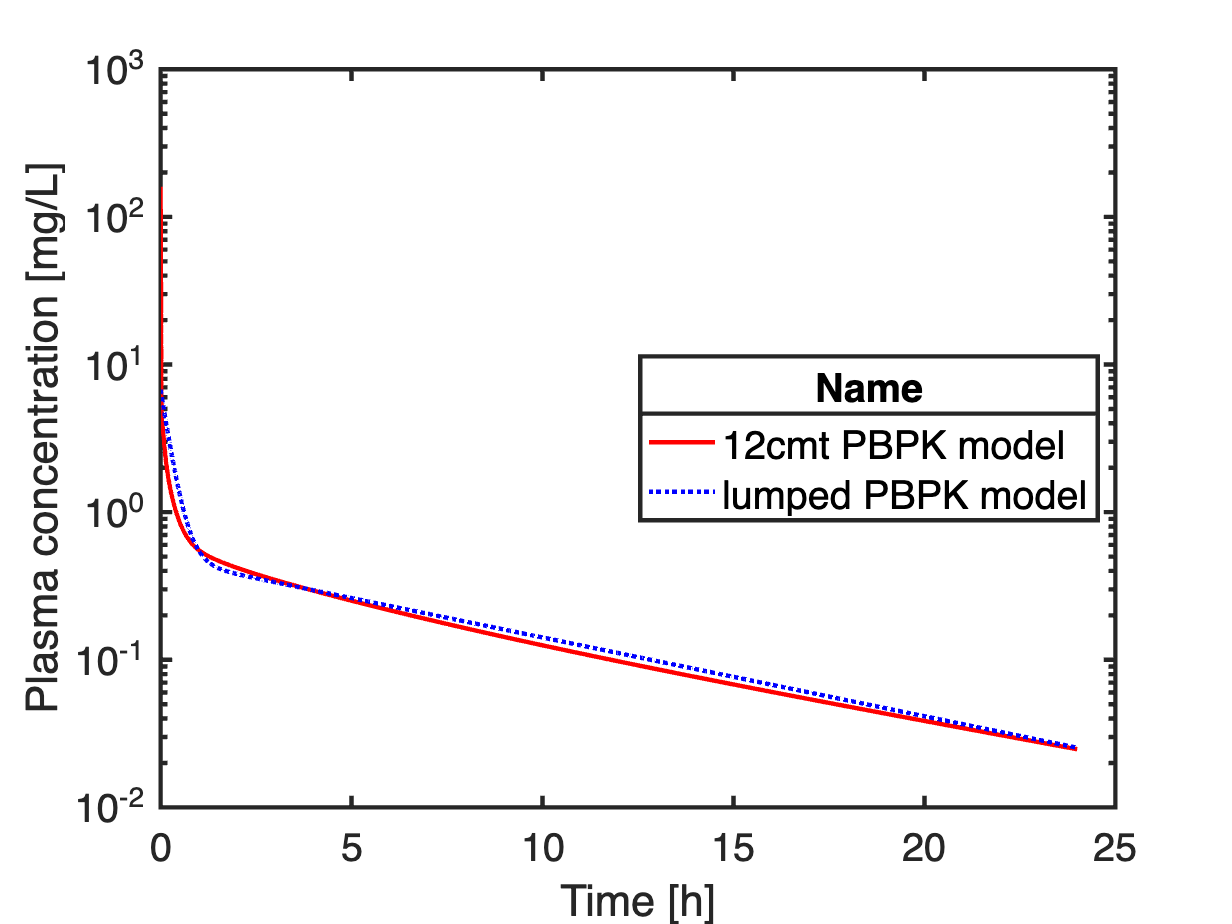

initialize(indv);
simulate(indv);

plot(indv,'group_by','Name','Site','pla', ...
    'ylabel','Plasma concentration','Yscalelog',true,'yunit','mg/L')

#### Scope of model lumping

For a model to be lumpable, it needs to provide the information specified in the function help of `lump_model()`.

help lump_model

 lump_model Lump a compartmental model
    L = lump_model(M, PARTITIONING), with an OdeModel object M and a cell 
    array of cellstr PARTITIONING containing names of model compartments,
    lumps model compartments of M in the same cellstr of PARTITIONING into
    a single compartment. The resulting lumped model is returned as an 
    OdeModel object L.
 
    Model compartments not specified in PARTITIONING will remain in
    separate compartments. Therefore, lump_model(M, {}) is always identical
    to M.
 
    Function lump_model relies on a few conventions in model M and if these
    are not fulfilled, an error will be thrown when L is initialized. More 
    precisely, the setup struct returned by model M must contain the 
    following fields:
    
    - a valid indexing struct setup.indexing.I, which enumerates the entire
      state vector X, say of length N;
    - a valid indexing struct setup.indexing.Id, whi

Currently, models `sMD_PBPK_12CMT_wellstirred()` and `sMD_PBPK_12CMT_permeabilityLimited()` provide the necessary information. 

#### More on the partitioning

An inspection of normalized concentrations allows to graphically evaluate which compartments are suitable for lumping:

indv = Individual('Virtual');

organs = {'adi','bon','gut','hea','kid','liv','lun','mus','ski','spl','art','ven'};
obs    = Observable('NormalizedConc',organs,'tot');

indv(1).name       = '12cmt PBPK model';
indv(1).physiology = Physiology('human35m'); 
indv(1).dosing     = Bolus('Amitriptyline', 0*u.h, 250*u.mg, 'iv');
indv(1).drugdata   = DrugData('Amitriptyline','species','human');
indv(1).sampling   = Sampling([0 24]*u.h, obs); 
indv(1).model      = sMD_PBPK_12CMT_wellstirred;
indv(1).model.options.tissuePartitioning = @rodgersrowland;

initialize(indv)
simulate(indv)

For this purpose, it is more practical to group by site (rather than stratifying by site)

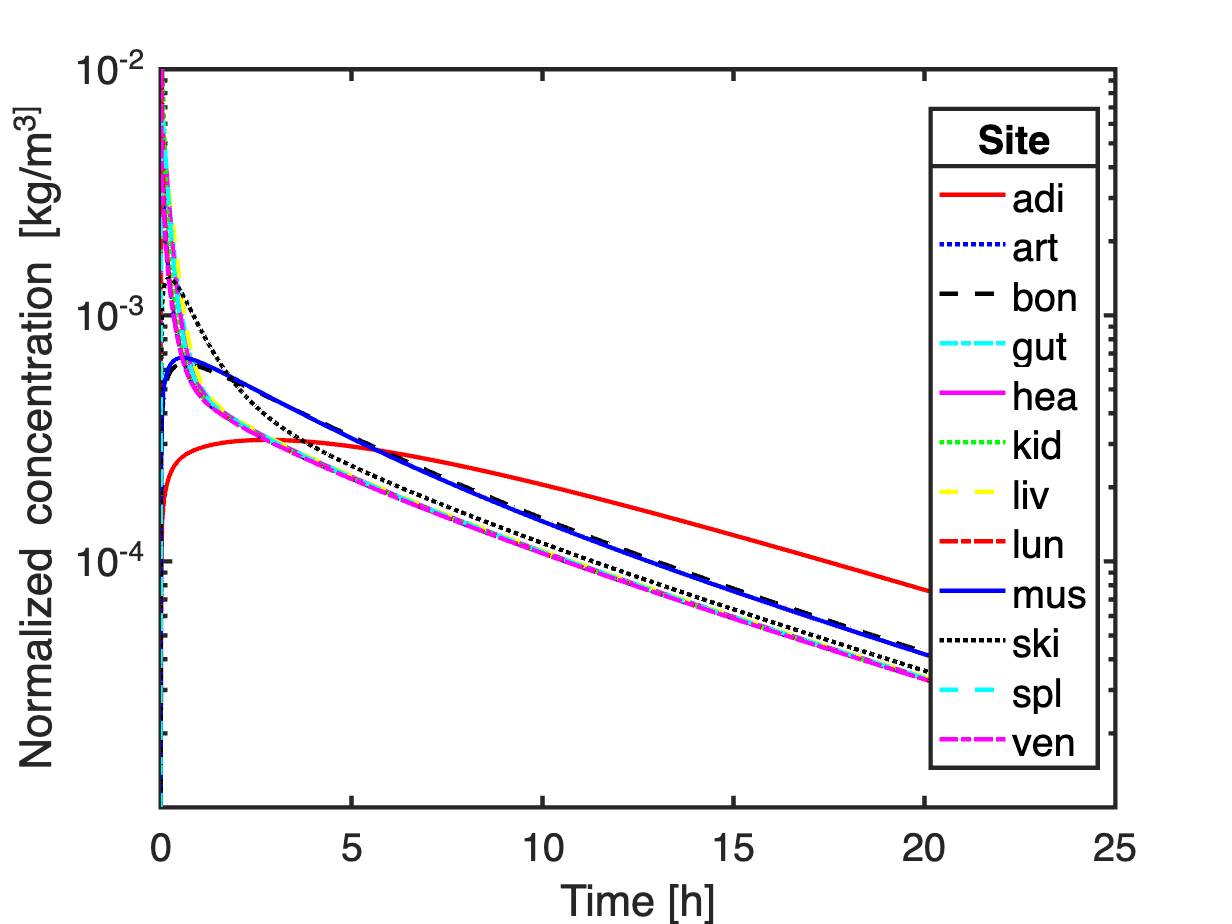

plot(indv,'ylabel','Normalized concentration','group_by','Site','yscalelog',true)
ylim([1e-5 1e-2])

Here, 4 types of distinct profiles can be seen: 

- adipose tissue;

- muscle and bone;

- skin;

- and the remaining tissues.

Hence, a partitioning scheme distinguishing these four groups can be expected to perform well.